Prepare Data

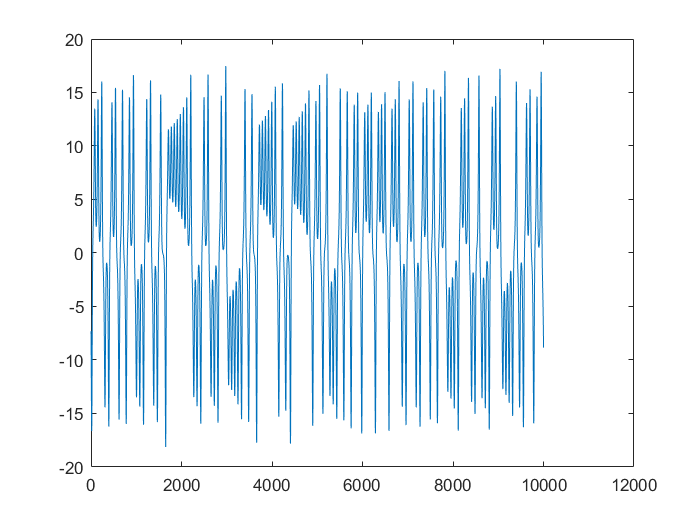

clc
clear
%Lorenz，rung（funciton，【ragne】，【initial】，accurancy）
a=0;
b=200;
c=[0 1 0];
h=0.01;
[t,y]=rung(@lorenz,[a b],c,h);
% data:train data and test data
pressure = y(1,10000:20000)';
figure
plot( pressure )

%% number of data
num_all_data = length( pressure );
% train data
num_train = floor( num_all_data * 0.75 );
% test data
num_test = num_all_data - num_train;
% translate data for narnet
y_train_nn = num2cell( pressure(1:num_train) )';
y_test_nn = num2cell( pressure(1+num_train:end))';


Build narnet

% feedback Delay
feedback_delays = 1:18;
% hidden Sizes
num_hd_neuron = 18;
% bulid narnet
net = narnet(feedback_delays, num_hd_neuron);
[Xs,Xi,Ai,Ts] = preparets(net,{},{}, y_train_nn);
net = train(net,Xs,Ts,Xi,Ai);
view(net)
Y = net(Xs,Xi);
perf = perform(net,Ts,Y);
fprintf( 'neural network: mse on training set : %.6f\n', perf );

neural network: mse on training set : 0.000000


Predict

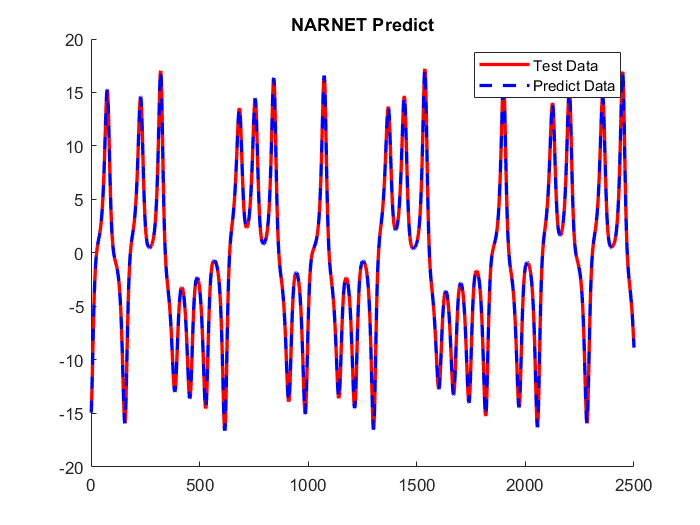

%% predict
yini = y_train_nn(end-max(feedback_delays)+1:end);
[Xs,Xi,Ai] = preparets(net,{},{},[yini y_test_nn]);
y_pred_nn = net(Xs,Xi,Ai)';
y_pred_nn = cell2mat( y_pred_nn );
y_test_nn = cell2mat( y_test_nn )';

%% plot，Calculate
figure
title('NARNET Predict')
hold on
plot( y_test_nn, 'r', 'linewidth', 2 );
plot( y_pred_nn, 'b--', 'linewidth', 2 );
legend({ 'Test Data', 'Predict Data'})
nn_per_error = mean(abs(y_pred_nn-y_test_nn) ./ y_test_nn);
nn_mse_error = mean( (y_pred_nn - y_test_nn).^2 );
xlim([0 inf ])


fprintf('nn model: relative error on test set: %.6f\n', nn_per_error);

nn model: relative error on test set: 0.000000


fprintf('nn model: mse on test set: %.6f\n', nn_mse_error);

nn model: mse on test set: 0.000000
